clear; clc; addpath('mfiles\'); addpath('skel\'); addpath('utils\')
% close all

**Adjustable Parameters, the Orders of AR Models that Fits x, y, v, and FIR Length**

% y <=> noisy speech; x <=> clean speech; v <=> additive noise; z <=> whole audio
% y = x + v
% z = [y,v,y,v,...]

N_y = 17; % AR order for y, 30 by visual inspection; 17 by MSE
N_v = 19; % AR order for v, 19 by visual inspection; 11 by MSE
% N_x = max(N_v, N_y); % AR order for x
N_x = N_y; % AR order for x

n_fir = 30; % Length of FIR Wiener filter

**Load Signal and Divide into Noise and Noisy Speech**

[z,fs] = audioread('EQ2401project1data2024.wav');
% Extract noisy speech samples 
speech_index = [4860:18780 26660:41212 51340:70001];
y = z(speech_index); % or y = z([4500:19000 26000:42000 51000:end]);
% soundsc(y, fs)
% Extract pure noise samples 
noise_index = [1:4700, 18900:26500, 41450:51000];
v = z(noise_index); % or v = z([1:4499, 18999:25999, 41999:50999]);
% soundsc(v, fs)
% Estimated speech samples 
% x = y - [v; v; v(1:length(y)-2 * length(v))];

**Compute Auto-Covariances**

L = 100; % L is the max index of auto-covariance(correlation).
r_yy = xcovhat(y, y, L);
r_vv = xcovhat(v, v, L);
r_xx = r_yy - r_vv; % property of acf, since we regard x and v are independent.
r_yx = r_xx;
R_yy = covhat(y, L);

**Compute Spectrum**

% Regard y,x,v as AR processes. The params for y and v can be estimated
% using ar_id (Least Square Method) in computer exercises
[A_v, sigma2_v] = ar_id(v, N_v);
[A_y, sigma2_y] = ar_id(y, N_y);

% For x, which we want to estimate, so do not have its accurate values. Instead, we
% have its auto-covariance(correlation).
% levinson, Levinson-Durbin recursion is to solve Yule-Walker equations, 
% where the coeffs and variance of a AR model can be computed based on its
% order and acf matrix.
[A_x, sigma2_x] = levinson(r_xx, N_x);

[PhiyyNum, PhiyyDen] = filtspec(1, A_y, sigma2_y);
[PhixyNum, PhixyDen] = filtspec(1, A_x, sigma2_x);

## **FIR**

SigmaYy = r_yy(1:n_fir);
SigmaVv = r_vv(1:n_fir);
SigmaXx = SigmaYy - SigmaVv;
SigmaYx = SigmaXx;
SigmaYY = R_yy(1:n_fir, 1:n_fir);

[xhatfir, thetahatfir] = firw(z, SigmaYx, SigmaYY);

## **Non-Causal**

[xhatnc, numnc, dennc] = ncw(z, PhixyNum, PhixyDen, PhiyyNum, PhiyyDen);

## **Causal**

m = 0; % filtering
[xhatc, numc, denc] = cw(z, PhixyNum, PhixyDen, PhiyyNum, PhiyyDen, m);

0 pole-zero(s) cancelled


**Plots and Commander Outputs**

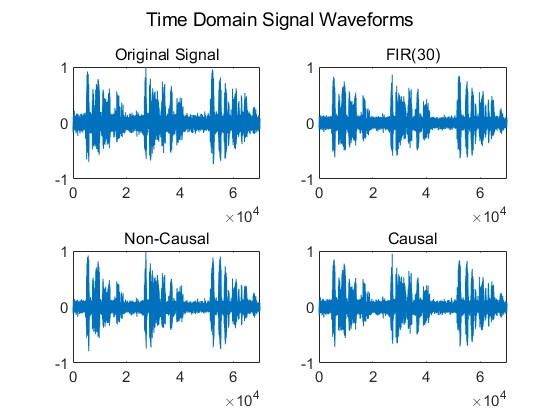

figure; % Plot Time Domain Waveforms
sgtitle('Time Domain Signal Waveforms', 'FontSize', 14);
subplot(2,2,1)
plot(0:length(z)-1, z)
ylim([-1 1])
xlim([0 7*10e3])
title('Original Signal');
subplot(2,2,2)
plot(0:length(xhatfir)-1, xhatfir);
ylim([-1 1])
xlim([0 7*10e3])
title(sprintf('FIR(%d)', n_fir))
subplot(2,2,3)
plot(0:length(xhatnc)-1, xhatnc);
ylim([-1 1])
xlim([0 7*10e3])
title('Non-Causal')
subplot(2,2,4)
plot(0:length(xhatc)-1, xhatc);
ylim([-1 1])
xlim([0 7*10e3])
title('Causal')

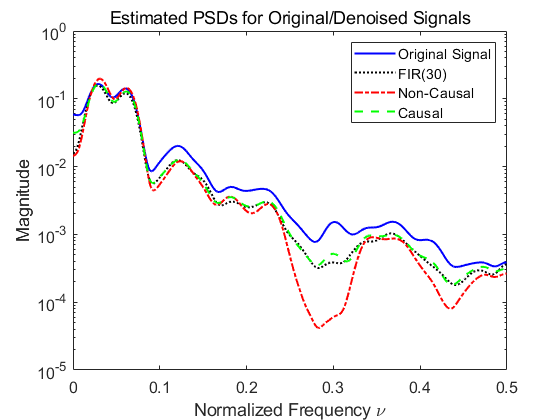


figure; % Plot PSDs estimated by Welch method
psd_comp(z,xhatfir,xhatnc,xhatc)
title('Estimated PSDs for Original/Denoised Signals')
xlabel('Normalized Frequency \nu')
ylabel('Magnitude')
legend('Original Signal',sprintf('FIR(%d)', n_fir),'Non-Causal','Causal')

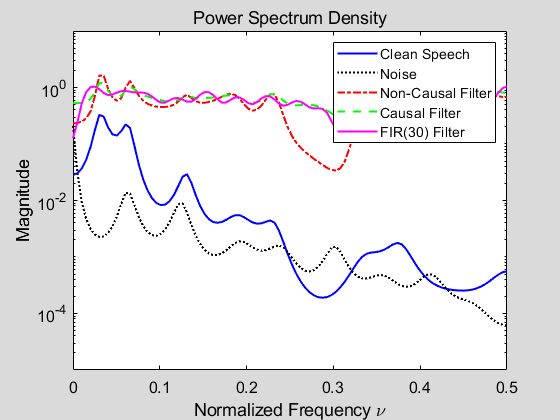


% % Print Noise Statistics Comparison
% fprintf('original noise mean: %f; original noise var: %f\n', mean(z(noise_index)), var(z(noise_index)));
% fprintf('noise mean after FIR: %f; noise var after FIR: %f\n', mean(xhatfir(noise_index)), var(xhatfir(noise_index)));
% fprintf('noise mean after Non-Causal: %f; noise var after Non-Causal: %f\n', mean(xhatnc(noise_index)), var(xhatnc(noise_index)));
% fprintf('noise mean after Causal: %f; noise var after Causal: %f\n', mean(xhatc(noise_index)), var(xhatc(noise_index)));

figure; % Spectrum Comparison,
spec_comp(A_x, sigma2_x, A_v, sigma2_v, numnc, dennc, numc, denc, thetahatfir);

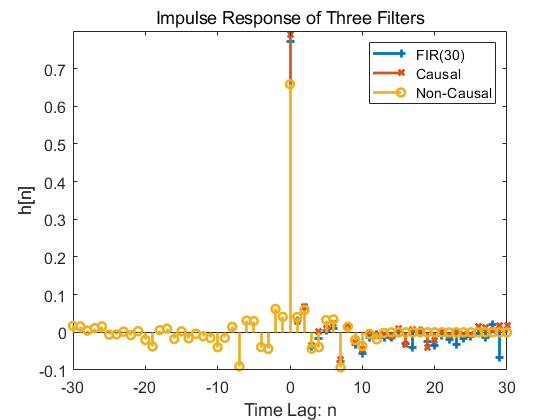


figure; % Plot impulse response of filters
t_c = (0:30)';
s_c = (t_c==0);
h_c = filter(numc, denc, s_c);
t_nc = (-30:30)';
s_nc = (t_nc==0);
h_nc = ncfilt(numnc, dennc, s_nc);
stem(0:length(thetahatfir)-1, thetahatfir, "+", LineWidth=2)
hold on
stem(t_c', h_c, "x", LineWidth=2)
hold on
stem(t_nc', h_nc, "o", LineWidth=2)
title('Impulse Response of Three Filters')
xlabel('Time Lag: n')
ylabel('h[n]')
legend(sprintf('FIR(%d)', n_fir), 'Causal', 'Non-Causal')

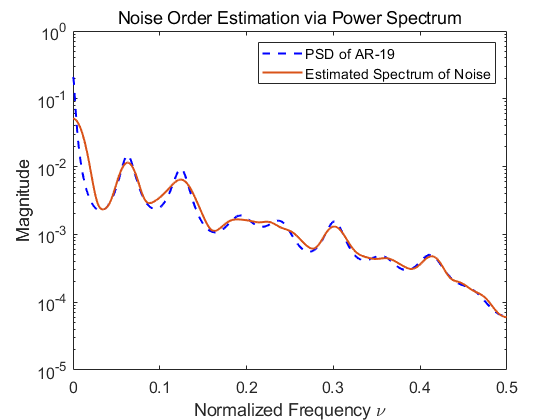


figure; % Plot Noise v psd 1. by Welch 2. fit by AR 
[~,~,~] = Spectra_AR(A_v, sigma2_v, 'half', 1);hold on
[~,~] = Spectra_Est(v, 'half', 1);
title('Noise Order Estimation via Power Spectrum')
xlabel('Normalized Frequency \nu')
ylabel('Magnitude')
legend(sprintf('PSD of AR-%d', N_v), 'Estimated Spectrum of Noise'); hold off

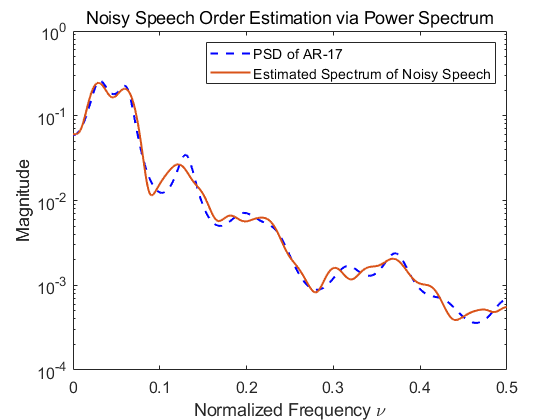


figure; % Plot Noisy Speech y psd 1. by Welch 2. fit by AR
[~,~,~] = Spectra_AR(A_y, sigma2_y, 'half', 1); hold on
[~,~] = Spectra_Est(y, 'half', 1);
title('Noisy Speech Order Estimation via Power Spectrum')
xlabel('Normalized Frequency \nu')
ylabel('Magnitude')
legend(sprintf('PSD of AR-%d', N_y), 'Estimated Spectrum of Noisy Speech'); hold off

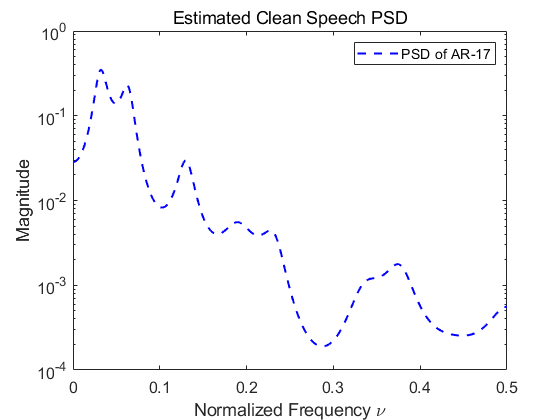


figure; % Plot Clean Speech psd fit by AR
[~,~,~] = Spectra_AR(A_x, sigma2_x, 'half', 1);
title('Estimated Clean Speech PSD')
xlabel('Normalized Frequency \nu')
ylabel('Magnitude')
legend(sprintf('PSD of AR-%d', N_x))

**Play Sound**

delta_t = length(z)/fs + 0.5;
soundsc(z, fs)
pause(delta_t)
soundsc(xhatfir, fs)
pause(delta_t)
soundsc(xhatnc, fs)
pause(delta_t)
soundsc(xhatc, fs)

**Save Audio Files**

% audiowrite('results\fir.wav', xhatfir, fs);
% audiowrite('results\nc.wav', xhatnc, fs);
% audiowrite('results\c.wav', xhatc, fs);